# Truncated SVD

Wir betrachten ein Modell (Beispiel 4.41 im Buch)

$g(t)=x_1  t + x_2 e^t + x_3 t^3 + x_4 \sin t$,   $t \in [0,4]$, 

mit exakten Parameterwerten  $(x_1^\ast,x_2^\ast,x_3^\ast,x_4^\ast)=(1.2,0.6,1.6,0.9)$.

Für $t_i=i\Delta t$, $i=1,\ldots,6$, $\Delta t=0.15$, werden "perfekte" Daten $b_i:=g(t_i)$ erzeugt.

Lösen des Ausgleichsproblems mit diesen Daten liefert eine sehr genaue numerische Lösung $x$:

xexakt= [1.2 0.6 1.6 0.9]';
t= 0.15*(1:6)';
b= xexakt(1)*t + xexakt(2)*exp(t) + xexakt(3)*t.^3 + xexakt(4)*sin(t);
A= [ t, exp(t), t.^3, sin(t)];
x= A\b;
fprintf('\n Fehler in der Lösung bei perfekten Daten:\n');


 Fehler in der Lösung bei perfekten Daten:


err1= norm(x-xexakt)/norm(xexakt)

err1 = 5.9211e-13

Aus einer Normalverteilung wird eine  Datenstörung erzeugt:

fprintf('\n Datenstörung: \n');


 Datenstörung: 


db= 0.01*randn(6,1)

db =     0.0054
    0.0183
   -0.0226
    0.0086
    0.0032
   -0.0131


und das lineare Ausgleichsproblem  mit gestörten Daten $\tilde b=b+\Delta b$ gelöst. Der relative Fehler in der berechneten Ausgleichslösung $\tilde x=A^\dagger \tilde b$ wird berechnet.  Das diesen  Parameterwerten entsprechende Modell  $\tilde g(t)$  (rote Kurve) und das Modell mit exakten  Paremeterwerten  $g(t)$ (blaue Kurve) sowie die Messdaten (o) werden geplottet.

fprintf('\n  Berechnete Lösung bei gestörten Daten:\n')


  Berechnete Lösung bei gestörten Daten:


xtilde= A\(b+db)

xtilde =    31.5194
    0.6288
   -3.2029
  -29.5720


fprintf('\n Fehler in der Lösung bei gestörten Daten:\n');


 Fehler in der Lösung bei gestörten Daten:


err2= norm(xtilde-xexakt)/norm(xexakt)

err2 = 19.0229

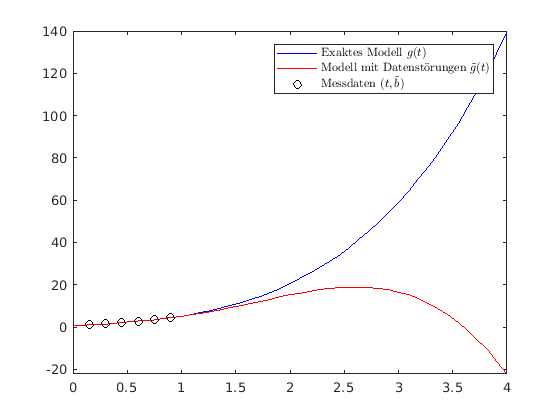

fplot(@(t) xexakt(1)*t + xexakt(2)*exp(t) + xexakt(3)*t.^3 + xexakt(4)*sin(t),[0 4],'b');
hold on
fplot(@(t) xtilde(1)*t + xtilde(2)*exp(t) + xtilde(3)*t.^3 + xtilde(4)*sin(t),[0 4],'r');
plot(t, b+db, 'ok');
leg1= legend('Exaktes Modell $g(t)$','Modell mit Datenst\"orungen $\tilde g(t)$','Messdaten $(t,\tilde b)$');
   set(leg1,'Interpreter','latex');
hold off

Beachte, dass $\tilde x$ sehr stark von den exakten Parameterwerten $x$ abweicht. Die sehr großen Fehler in $\tilde x$ deuten auf eine schlechte Kondition hin. 

Berechnung der Singulärwertzerlegung und der Konditionszahl:

[U,S,V]= svd(A);
S

S =     4.8656         0         0         0
         0    0.5347         0         0
         0         0    0.1784         0
         0         0         0    0.0003
         0         0         0         0
         0         0         0         0


Konditionszahl= S(1,1)/S(4,4)

Konditionszahl = 1.7346e+04

Wir verwenden eine TSVD-Regularisierung, wobei der kleinste Singulärwert "abgeschnitten" (d.h., durch Null ersetzt) wird:

S_TSVD= S;
S_TSVD(4,4)=0;
xtilde_TSVD= V*pinv(S_TSVD)*U'*(b+db)

xtilde_TSVD =     1.1644
    0.6093
    1.5901
    0.9100


fprintf('\n Fehler in der TSVD-Lösung bei gestörten Daten:\n');


 Fehler in der TSVD-Lösung bei gestörten Daten:


err_TSVD= norm(xtilde_TSVD - xexakt)/norm(xexakt)

err_TSVD = 0.0173

Die Parameterwerte $\tilde x_\mathrm{TSVD}$ sind deutlich besser und der Fehler daher wesentlich kleiner. Das diesen  Parameterwerten entsprechende Modell $\tilde g_{\rm SVD}(t)$ (rosa Kurve) und das Modell mit exakten  Paremeterwerten $g(t)$  (blaue Kurve) sowie die Messdaten (o) werden geplottet.

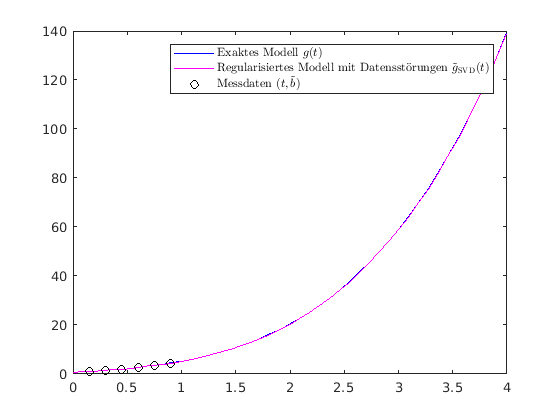

fplot(@(t) xexakt(1)*t + xexakt(2)*exp(t) + xexakt(3)*t.^3 + xexakt(4)*sin(t),[0 4],'b');
hold on
fplot(@(t) xtilde_TSVD(1)*t + xtilde_TSVD(2)*exp(t) + xtilde_TSVD(3)*t.^3 + xtilde_TSVD(4)*sin(t),[0 4],'m');
plot(t, b+db, 'ok');
leg2= legend('Exaktes Modell $g(t)$','Regularisiertes Modell mit Datensst\"orungen $\tilde g_{\rm SVD}(t)$', ...
    'Messdaten $(t,\tilde b)$');
   set(leg2,'Interpreter','latex');

# Aktivität

Man kann das Programm öfter wiederholen, wobei dann jedes mal eine andere Datenstörung (aus der Normalverteiliung) erzeugt wird. 